(2a) My method of calculating probabilities do not need to implement encode and decode. However, for reference, I have coded versions of these functions in the Appendix.

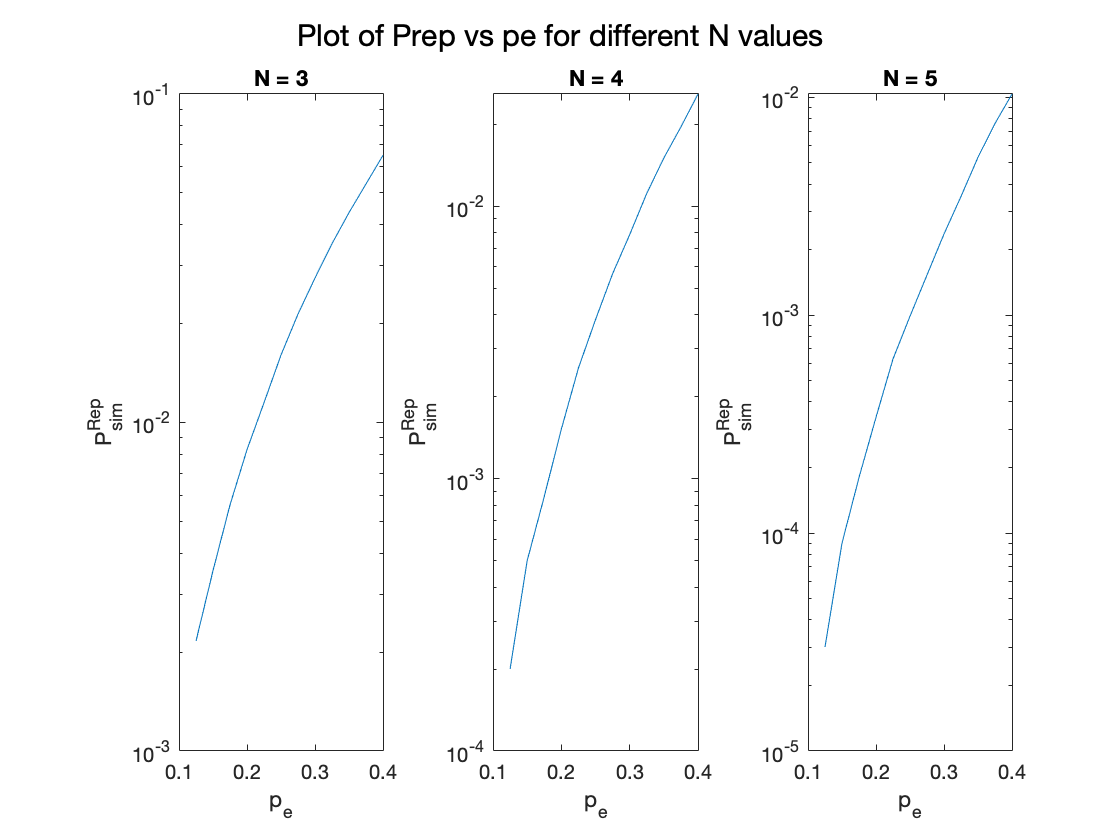

figure(1);
sgtitle("Plot of Prep vs pe for different N values");
N = [3, 4, 5];
pe = (0.125:0.025:0.4);
for n = N
    rvals = rand(100000, n);
    prep = zeros(length(pe));
    for x = 1:length(pe)
        prep(x) = sum(sum(rvals < pe(x), 2) == n) / 100000;
    end
    subplot(1, 3, n - 2);
    semilogy(pe, prep);
    title("N = " + n);
    xlabel("p_e");
    ylabel("P^{Rep}_{sim}");
end

(2b) For all to fail, we need probability of pe every single time. Thus, for N = n, the probability of a failed transmissions is pe^n.

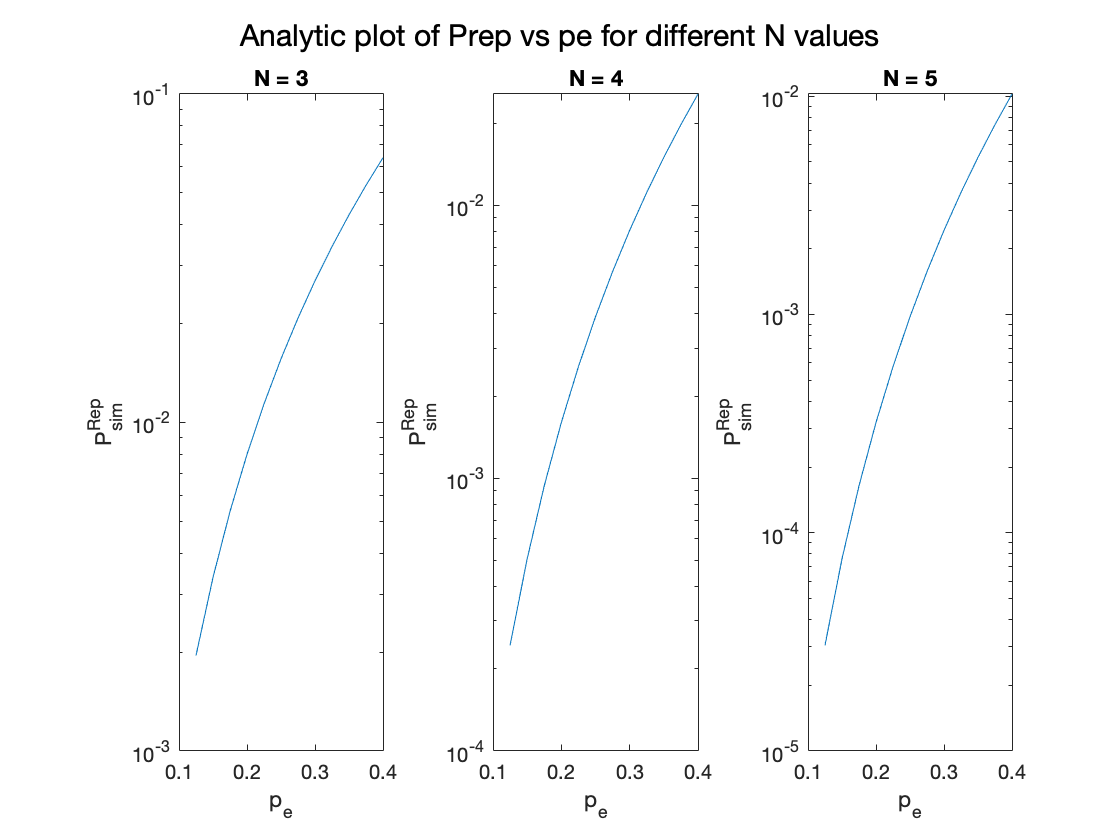

figure(2);
sgtitle("Analytic plot of Prep vs pe for different N values");
for n = N
    prep = power(pe, n);
    subplot(1, 3, n - 2);
    semilogy(pe, prep);
    title("N = " + n);
    xlabel("p_e");
    ylabel("P^{Rep}_{sim}");
end

(2c) In this case, we are not allowed to have two failed bits because otherwise the final string is not recoverable

Thus, we can make a slight modification to our code to accomplish this: instead of testing whether the number of failed bits is equal to N, we make sure that the number of successful bits is greater than or equal to N - 1. Thus, the failed attempts are where the number of successful bits is less than N - 1.

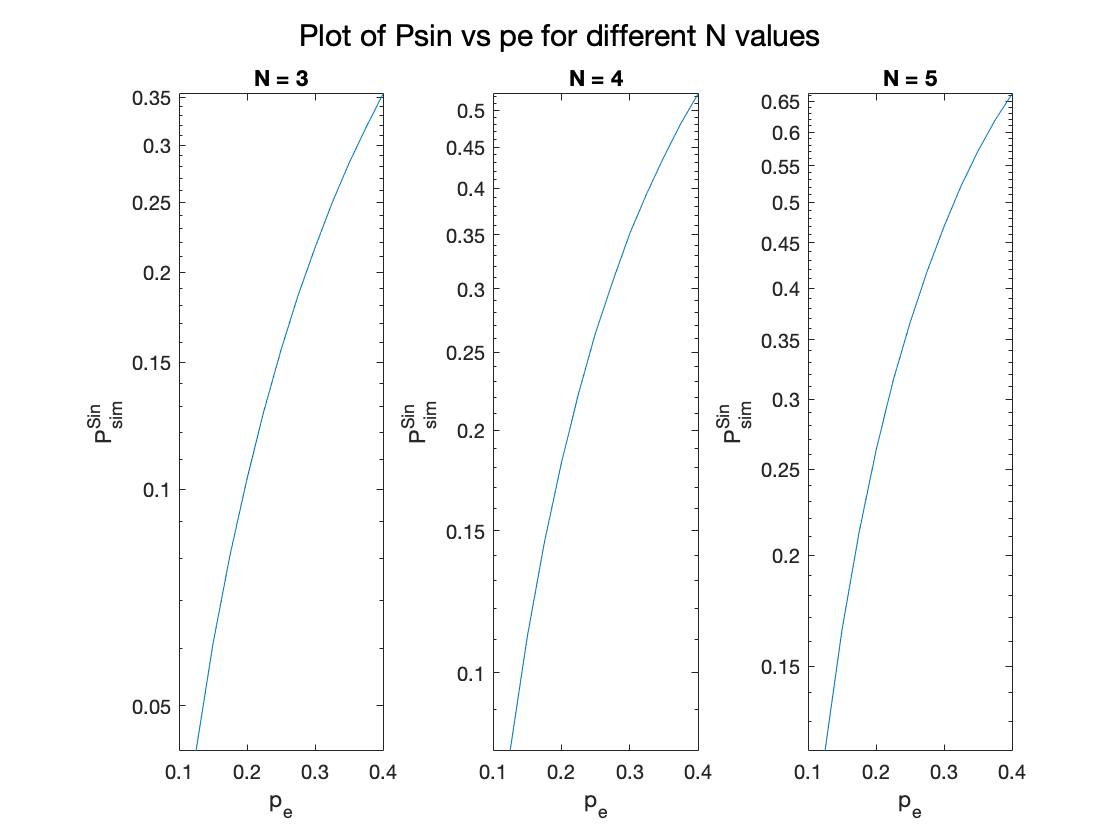

figure(3);
sgtitle("Plot of Psin vs pe for different N values");
N = [3, 4, 5];
pe = (0.125:0.025:0.4);
for n = N
    rvals = rand(100000, n);
    prep = zeros(length(pe));
    for x = 1:length(pe)
        prep(x) = sum(sum(rvals > pe(x), 2) < n - 1) / 100000;
    end
    subplot(1, 3, n - 2);
    semilogy(pe, prep);
    title("N = " + n);
    xlabel("p_e");
    ylabel("P^{Sin}_{sim}");
end

And for the analytic version:

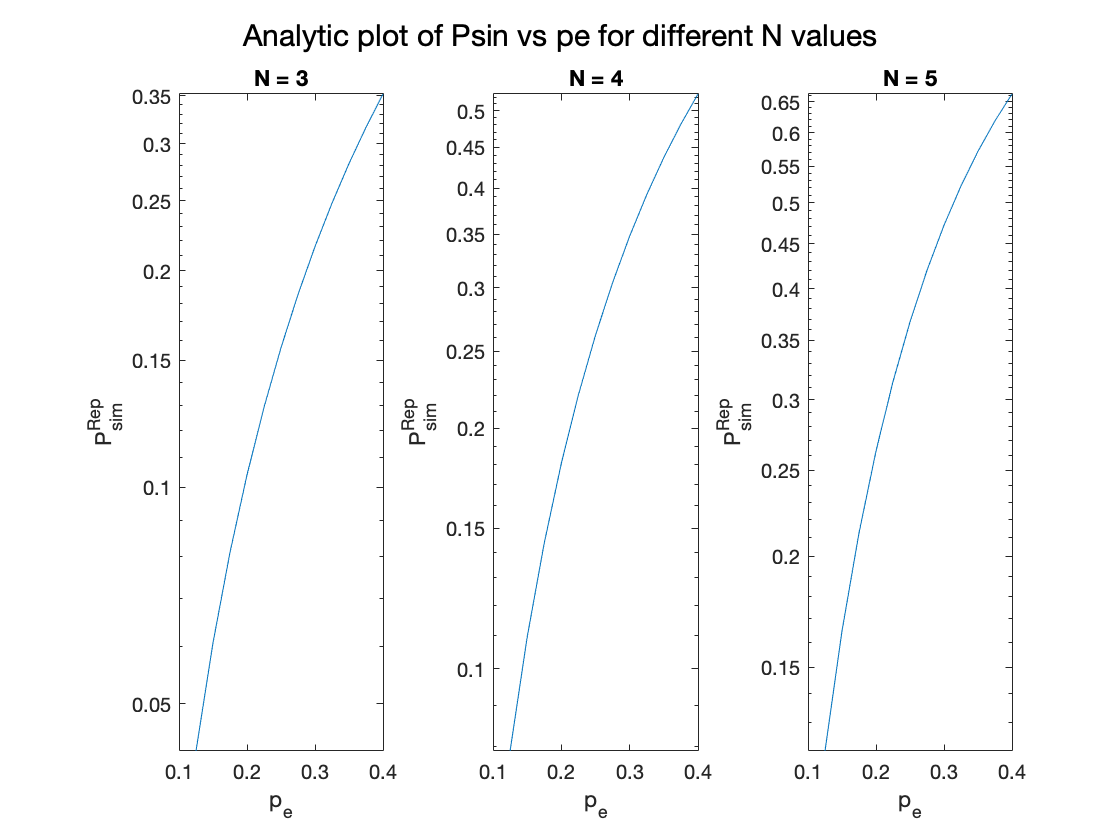

figure(4);
sgtitle("Analytic plot of Psin vs pe for different N values");
for n = N
    prep = 1 - power(1 - pe, n) - n .* pe .* power(1 - pe, n - 1);
    subplot(1, 3, n - 2);
    semilogy(pe, prep);
    title("N = " + n);
    xlabel("p_e");
    ylabel("P^{Rep}_{sim}");
end

(2d) The plot of P_Sin is much, much larger than that of P_Rep. Which shows that it is much more likely that the transmission fails for Single-bit parity code.

(2e) Repetition code is useful when you want your transmission to be very perfect and have absolutely no loss of data. On the other hand, single-bit parity code transmission is much faster (n times as fast), but has a lot higher chance of dying. For example, transferring passwords across lines must be accurate to the bit. However, if you are in need of fast transmission and not entirely perfect signal transmission, like in a phone call, single-bit parity code would be better. Note that 0.5 error is too high haha but if we use double-bit or triple-bit I think it would be more feasible yet still not that slow.